%clear 

%% parameters for running batch script
% parameters for loading data
task      = 'aur';
beapp_tag = '_updated_trials_updated_trigger_notch_erpfilt_noblcorr';
data_path = fullfile( 'Z:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      'EEG','Participant_Data','03_Processed_Data' );
file_tag = [beapp_tag '_2022-12-12_yb_.1-30_seg_run_in_beapp_100msbl_corr_2'];
file_tag = [beapp_tag '_2022-09-01_gp']

file_tag = '_updated_trials_updated_trigger_notch_erpfilt_noblcorr_2022-09-01_gp'

file_tag = ['_HAPPE_V3_2023-01-19_yb_noexclusion_200msbl'];
file_tag = ['_HAPPE_V3_2023-01-20_yb_noexclusion_full_200ms_individ_bl'];
file_tag = [beapp_tag, '_2023-02-13_yb_50ms']

file_tag = '_updated_trials_updated_trigger_notch_erpfilt_noblcorr_2023-02-13_yb_50ms'

%file_tag = [beapp]
% parameters for processing
method    = 'conds_avg';
rois      = {'E52'};
groups    = {'TD','ASD'};
%erps      = {'N13','P25','P50','N80','P100','N140','P300','P4','P190','N300';  % components to calculate/plot
exclude   = {};
erps = {'N13','N20','P25', 'P50', 'N80', 'P100','N140','P300','P4' ,'P190','N300','N13_P25_dist','N20_P25_dist','P50_N80_dist','N80_P100_dist','P100_N140_dist','N140_P300_dist','P300_P4_dist'};
%erps = {'N20','N140'}
%erps = {'P300'}
% parameters for plots
rescale   = false;
save_figs = true;
cond_names = {'1_mN'	,'2_mN',	'5_mN',	'10_mN',	'20_mN'	,'40_mN'	,'50_mN'	,'75_mN',	'100_mN'};
cond_names = {'2mN','5mN','10mN','20mN','40mN','50mN','75mN'}

cond_names = 1×7 cell array
    {'2mN'}    {'5mN'}    {'10mN'}    {'20mN'}    {'40mN'}    {'50mN'}    {'75mN'}


%cond_names = 'baseline'
colors    = {'#4444c9','#32a852','#db4214'};
colors = {'red','green','blue','yellow'};
params = {'CL EEG','CL ERP','N EEG','N ERP'};
% colors    = {'#000','#444','#888','#ccc'};
 x_label   = 'Intentisity (mN)';
%x_label   = 'Condition';
y_label   = 'Average Amplitude (\muV)';
%xlims     = [1 5];

%% load batch information
%task_path = get_task_path(task);
save_path = 'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Pilot_Data\02_Raw_Data\Aurora\Aurora_20ms','erp';

save_path = 'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Pilot_Data\02_Raw_Data\Aurora\Aurora_20ms'

task_path_batch =fullfile('Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Pilot_Data\02_Raw_Data\Aurora\Aurora_20ms','erp',['erp' file_tag '.mat']);
task_path_batch =     'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Participant_Data\03_Processed_Data\09_Aurora\erp\erp_3_14_23_notch_filt_50msbl_2023-03-15_yb_50ms.mat';
task_path_batch =     'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Participant_Data\03_Processed_Data\09_Aurora\erp\erp_3_14_23_notch_filt_100msbl_2023-03-15_yb_noblcorr.mat';
task_path_batch =     'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Participant_Data\03_Processed_Data\09_Aurora\erp\erp_3_16_23_notch_filt_100msbl_jointprob_meandet_2023-03-16_yb_100msblcorr_meandet_all'

task_path_batch = 'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Participant_Data\03_Processed_Data\09_Aurora\erp\erp_3_16_23_notch_filt_100msbl_jointprob_meandet_2023-03-16_yb_100msblcorr_meandet_all'

task_path_batch =     'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Participant_Data\03_Processed_Data\09_Aurora\Baseline\erp\erp_3_16_23_bl_2023-03-17_baseline.mat'

task_path_batch = 'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Participant_Data\03_Processed_Data\09_Aurora\Baseline\erp\erp_3_16_23_bl_2023-03-17_baseline.mat'

task_path_batch =     'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Pilot_Data\02_Raw_Data\Aurora\01_Aurora_Adult_Pilot\erp\erp_3_16_23_notch_filt_100msbl_30_200_aligned_2023-03-20_trial_aligned_30_200.mat'

task_path_batch = 'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Pilot_Data\02_Raw_Data\Aurora\01_Aurora_Adult_Pilot\erp\erp_3_16_23_notch_filt_100msbl_30_200_aligned_2023-03-20_trial_aligned_30_200.mat'

task_path_batch =     'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Pilot_Data\02_Raw_Data\Aurora\01_Aurora_Adult_Pilot\02_Aurora_mffs\erp\erp_aligned_2023-03-22_trial_aligned_30_200.mat'

task_path_batch = 'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Pilot_Data\02_Raw_Data\Aurora\01_Aurora_Adult_Pilot\02_Aurora_mffs\erp\erp_aligned_2023-03-22_trial_aligned_30_200.mat'

task_path_batch =     'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Pilot_Data\02_Raw_Data\Aurora\01_Aurora_Adult_Pilot\02_Aurora_mffs\erp\erp_aligned_2023-03-22_trial_6_end_aligned_30_200.mat'

task_path_batch = 'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Pilot_Data\02_Raw_Data\Aurora\01_Aurora_Adult_Pilot\02_Aurora_mffs\erp\erp_aligned_2023-03-22_trial_6_end_aligned_30_200.mat'

task_path_batch =     'Z:\Groups\SPA\01_Data_Raw_Summary_Processed\EEG\Pilot_Data\03_Processed_Data\01_Aurora_Adult_Pilot\02_Aurora_mffs\erp\erp_aligned_2023-03-24_trial_6_end_aligned_30_200.mat';
task_path_batch =     'C:\Users\ch220650\Desktop\segment_aligned\erp\erp_aligned_2023-03-25_trial_6_end_aligned_bl_rm.mat';
task_path_batch =     'C:\Users\ch220650\Desktop\segment_aligned\erp\erp_aligned_2023-03-28_trial_6_end_aligned_bl_rm_1_100_ica.mat'

task_path_batch = 'C:\Users\ch220650\Desktop\segment_aligned\erp\erp_aligned_2023-03-28_trial_6_end_aligned_bl_rm_1_100_ica.mat'

task_path_batch =     'C:\Users\ch220650\Documents\02_Programming_Projects\03_BCH_Projects\Aurora_files\segment_aligned\erp\erp_aligned_2023-04-12_trial_6_end_aligned_bl_rm_1_100_ica.mat';
%task_path_batch = 'C:\Users\ch220650\Desktop\segment_aligned\erp\erp_aligned_2023-03-26_trial_6_end_aligned_bl_rm.mat';
task_path_batch =     'C:\Users\ch220650\Documents\02_Programming_Projects\03_BCH_Projects\Aurora_files\segment_aligned\erp\erp_aligned_2023-04-13_trial_6_end_aligned_bl_rm_1_100_ica.mat';
load(task_path_batch,'batch','data');
batch.method  = method;
batch.rescale = rescale;
exclude = {'pAuro'}

exclude = 1×1 cell array
    {'pAuro'}


% calculate or load group averages
%[data,batch] = calculate_erp_grp_avgs(batch,exclude);

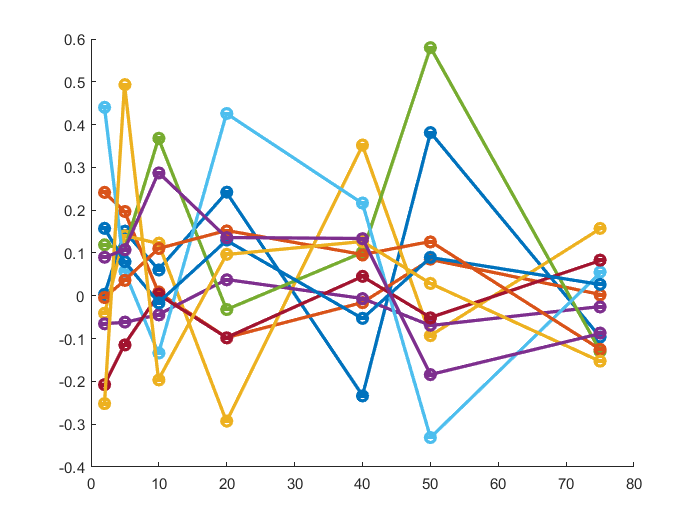

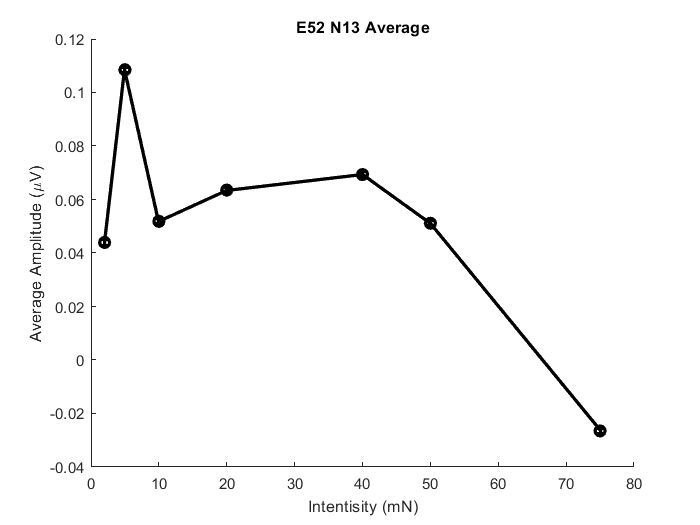

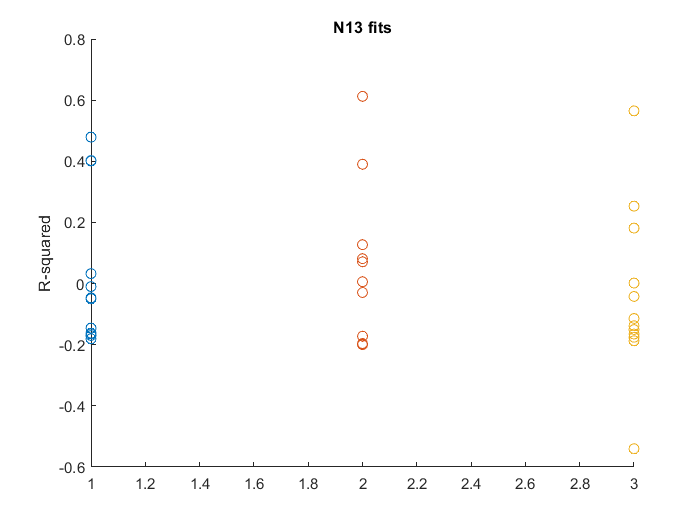

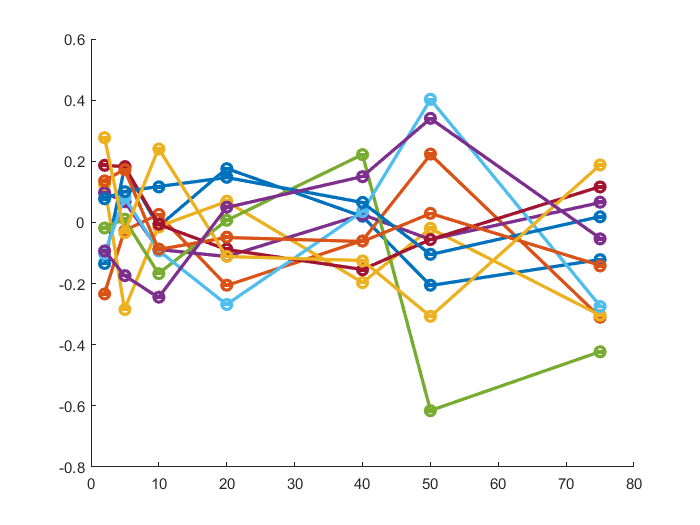

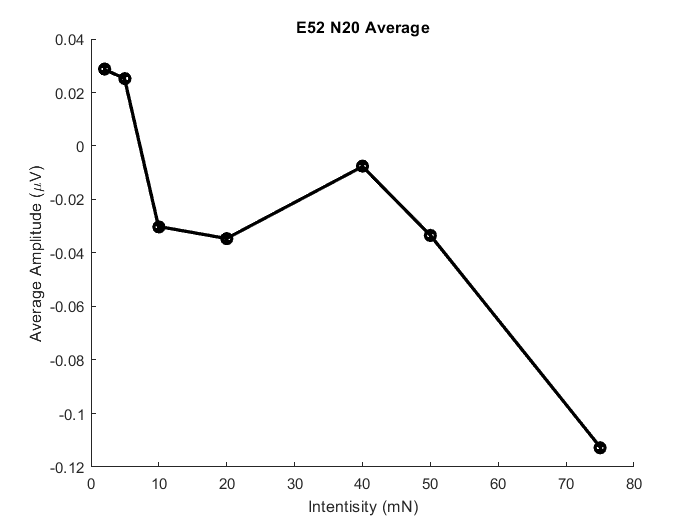

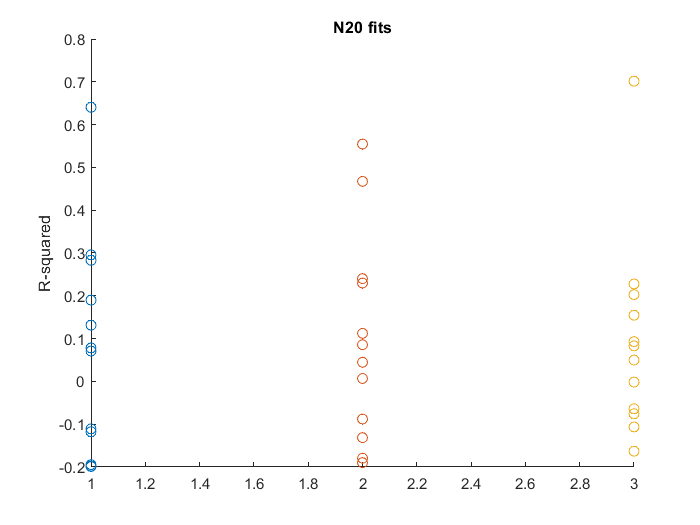

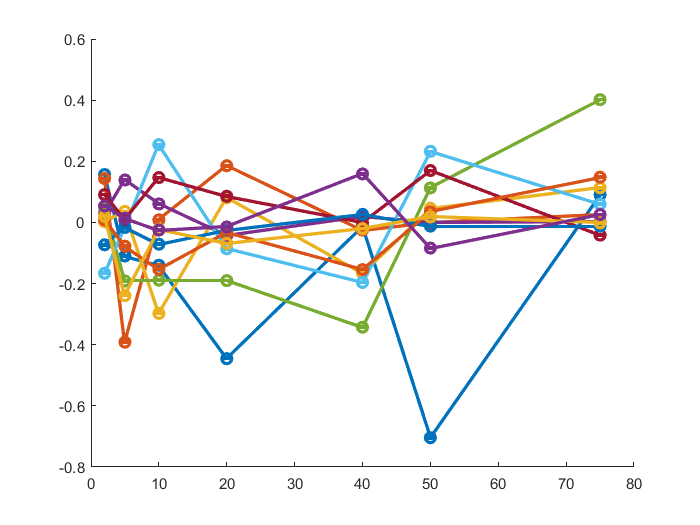

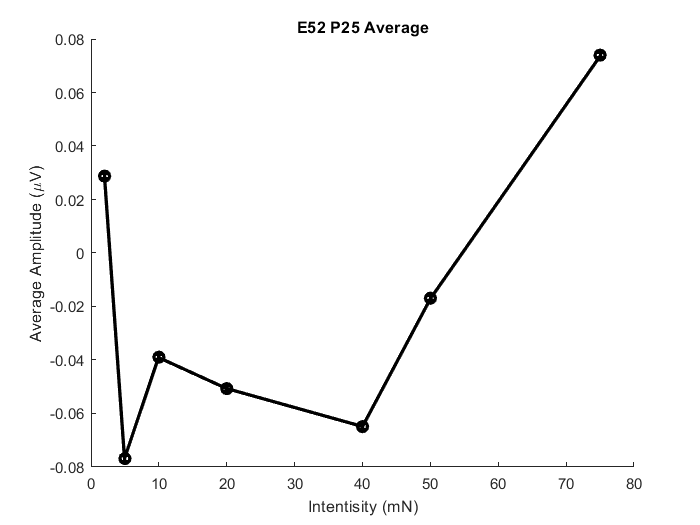

a = 5

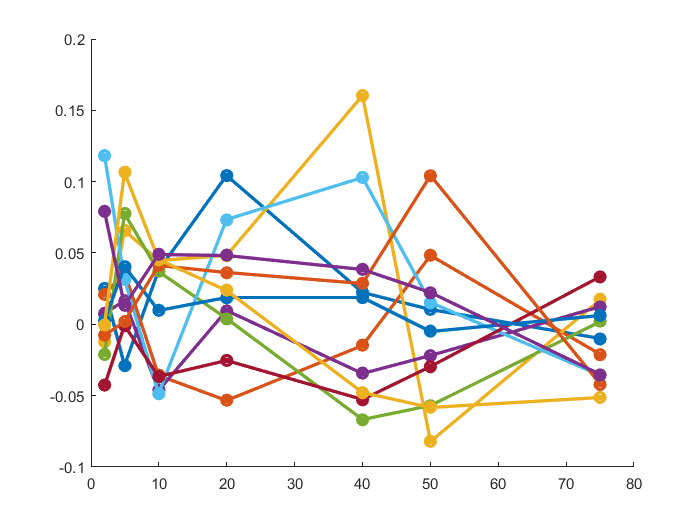

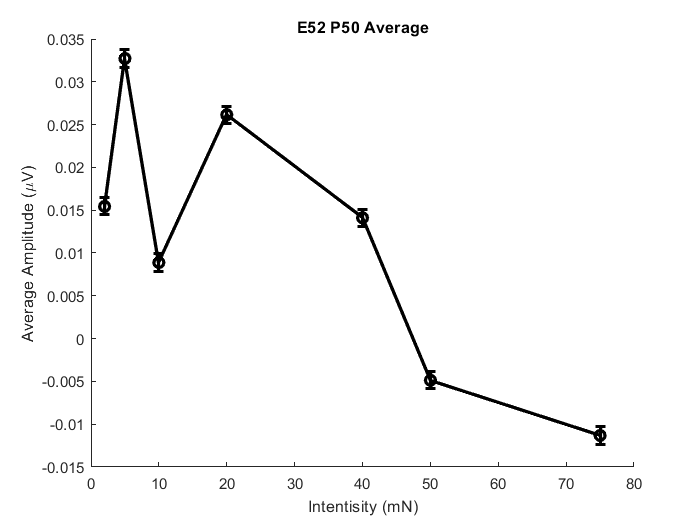

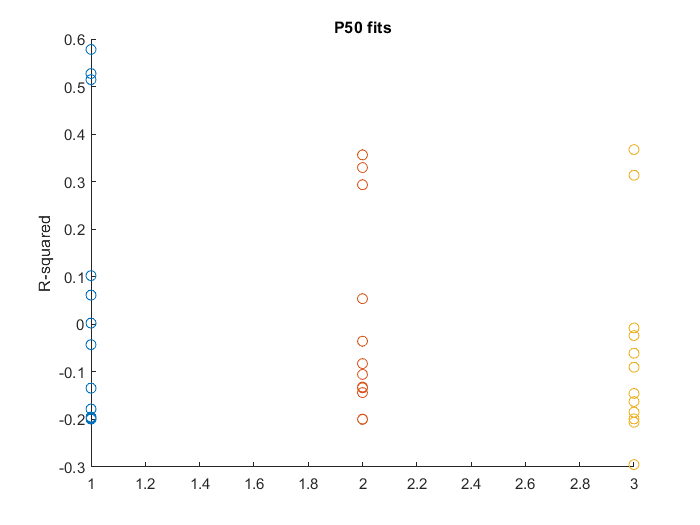

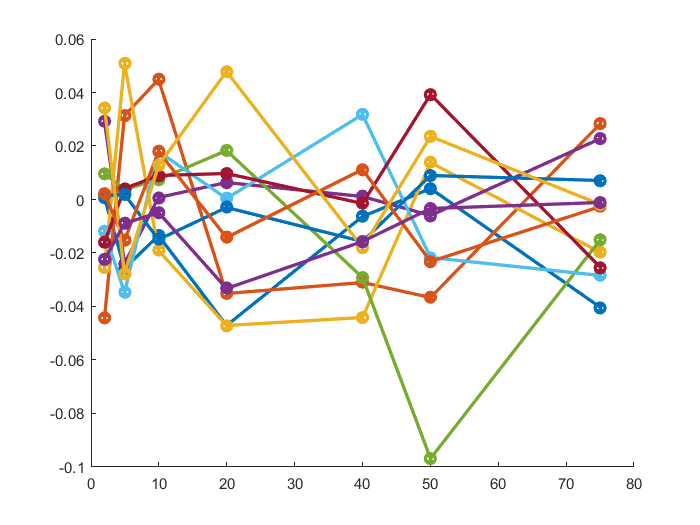

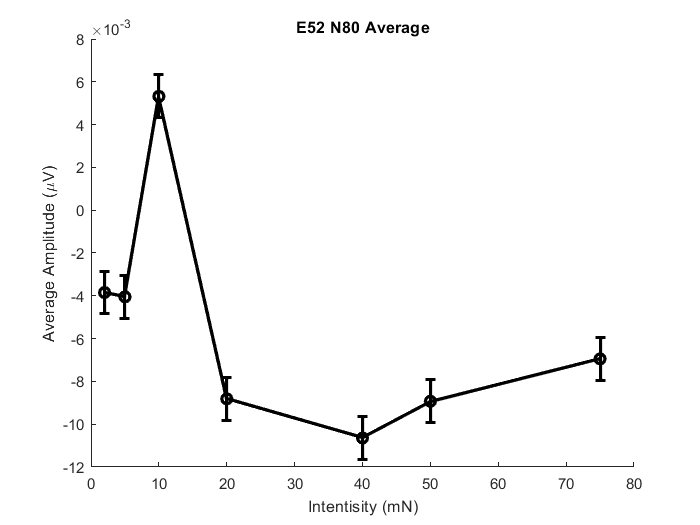

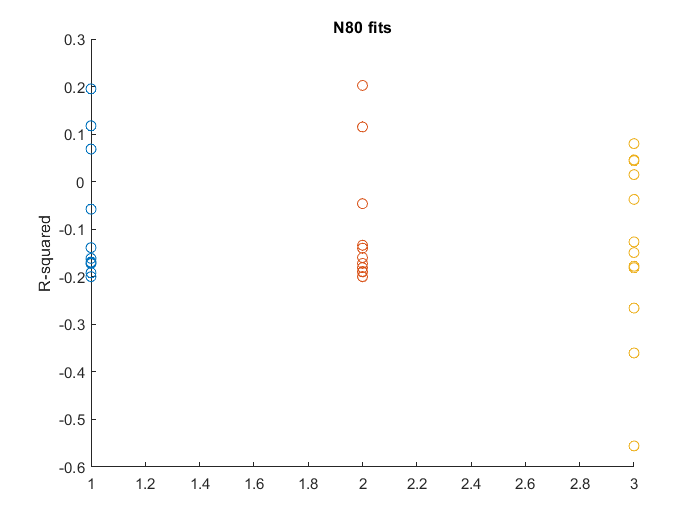

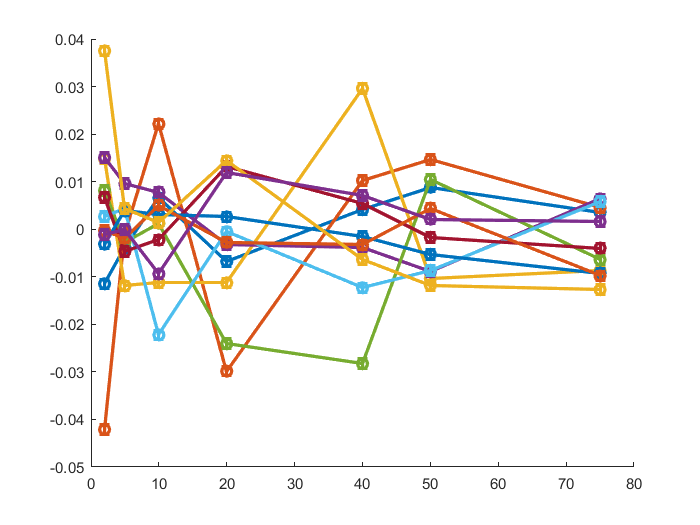

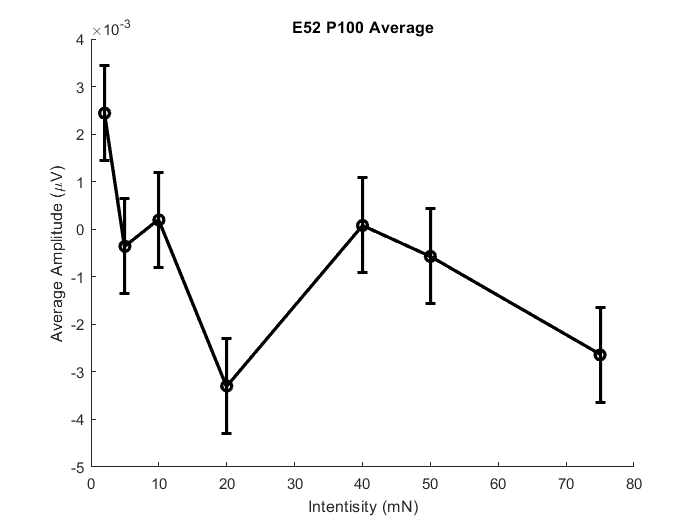

method_name = get_method_plot_name(method);

% iterate through group
n_grps = length(groups);
n_rois = length(rois);
n_erps = length(erps);
for i_r = 1:n_rois
    roi = rois{i_r};
    for i_e = 1:n_erps
        % initialize variables
        grp_avg = []; grp_err = []; grp_labels = cell(1,n_grps); grp_si = [];
        
        % skip if ERP component not in ROI
        erp = erps{i_e};
        if ~isfield(data.(roi),erp)
            continue
        end
if i_e == 4
    a=5
end
      %  get group data
%         for i_g = 1:n_grps
%             % get group data
%             group = groups{i_g};
%             avg = data.(group).(roi).(erp).avg; err = data.(group).(roi).(erp).err;
%             grp_avg = [grp_avg; avg];
%             grp_err = [grp_err; err];
%             grp_labels{i_g} = [group ', n=' int2str(batch.groups.(group).N)];
% 
%             % calculate suppression index for TSS
%             if contains(task,'tss')
%                 grp_si = [grp_si; 1 - avg(3)/(avg(1)+avg(2))];
%             end
%         end
        p_ids =unique(cellfun(@(x) x(1:5),fields(data.(roi).(erp)),'UniformOutput',false));
       p_id_labels = p_ids;
    %   p_id_labels{3}= 'pYB'
        % generate plots
                f = figure; hold on
                count = 1;
                s_count = 1;
                for i_p = 1:length(p_ids)
                    p_id = p_ids{i_p};
                    
                    if contains(erp,'dist')
                        curr_data = abs(data.(roi).(erp).(strcat(p_ids{i_p},'_',method)));
                    else
                    curr_data = data.(roi).(erp).(strcat(p_ids{i_p},'_',method));
                    end
                    x = [2 5 10 20 40 50 75]; x = x';% x=x(4:end);
                    y = curr_data;%(4:end);
                    %plot(y); hold on
                    %get fits for different curves
                    fit_types = {'poly1','exp1','poly1';...
                                    'Lin','Exp1','Log'};
                    for f_t = 1:size(fit_types,2)
                        if strcmp(fit_types{2,f_t},'Log')
                            x_temp = log(x);
                        else
                            x_temp = x;
                        end

                        if strcmp(fit_types{2,f_t},'Sig')
                            ft = fittype( 'a/(1+exp(-b*x))', 'independent', 'x', 'dependent', 'y' );
                        else
                            ft = fit_types{1,f_t};
                        end
                       [output] =polyfit(x(1:end),y(1:end),1);

                        slope_struct.(erp)(s_count).slope = output(1);
                        slope_struct.(erp)(s_count).intercept = output(2);
                        slope_struct.(erp)(s_count).type = p_id;
                        s_count = s_count+1;
                    [fitobject,gof,output] = fit(x_temp,y,ft);
                    gof_fields = fields(gof)  ;
                   % for i_f = 1:length(fields(gof))
                        fit_struct.(erp)(count).type = (strcat(fit_types{2,f_t},p_id,'_','rsquare'));
                       fit_struct.(erp)(count).value = gof.adjrsquare;

                       count = count+1;
                    end

                  %  plot
                  errorbar([2 5 10 20 40 50 75],curr_data,[repmat(.001,1,7)],'-o','LineWidth',2);%'Color',colors{i_p})

                 
                    if ~any(strcmp(p_ids{i_p},exclude))
                        all_data(i_p,:) = curr_data;
                    end
                 %   title(strcat(p_id,'_',erp,'_fits'))
                end
                    data.TD.(roi).(erp).avg = nanmean(all_data,1);                
                       
                figure(); hold on
                errorbar([2 5 10 20 40 50 75], data.TD.(roi).(erp).avg,[repmat(.001,1,7)],'-o','LineWidth',2,'Color','black');%'Color',colors{i_p})

                legend([p_id_labels;'groupavg'])
                fig_title = [roi ' ' erp ' ' method_name];
                if batch.rescale
                    fig_title = [fig_title ', rescaled'];
                end
                title(plaintext(fig_title))
                xlabel(x_label), ylabel(y_label)
                %xticks([1:7])
                %xlim([4 8])
                %xticklabels('2mn')
                % ylim([min(data.TD.(roi).(erp).avg)-.01 ,max(data.TD.(roi).(erp).avg)+.01])

                 for f_t = 1:size(fit_types,2)
                        if strcmp(fit_types{2,f_t},'Log')
                            x_temp = log(x);
                        else
                            x_temp = x;
                        end
                        if strcmp(fit_types{2,f_t},'Sig')
                            ft = fittype( 'a/(1+exp(-b*x))', 'independent', 'x', 'dependent', 'y' );
                        else
                            ft = fit_types{1,f_t};
                        end
                    [fitobject,gof,output] = fit(x_temp,nanmean(all_data,1)',ft);
                    gof_fields = fields(gof)  ;
                   % for i_f = 1:length(fields(gof))
                        fit_struct.(erp)(count).type = (strcat(fit_types{2,f_t},'group_avg','_','rsquare'));
                       fit_struct.(erp)(count).value = gof.adjrsquare;
                       count = count+1;
                  end
                clear all_data

                 types = {'Lin','Log','Exp','Sig'};
                  figure(); hold on
                  for type = 1:length(types)
                   curr_rsquared = [fit_struct.(erp)(find(contains({fit_struct.(erp).type},types{type}))).value];
                   scatter(repmat(type,1,length(curr_rsquared)),curr_rsquared);
                   hold on;
                  end
                                    legend(types)

                  title(strcat(erp,' fits'))
                  ylabel('R-squared')
                
                % save figure
                if 0
                    plot_fname = strrep([task '_' fig_title],' ','_');
                    fig_path = fullfile(batch.path_task_figs,[plot_fname beapp_tag '.jpg']);
                    if ~exist(batch.path_task_figs,'dir')
                        mkdir(batch.path_task_figs);
                    end
                    saveas(f,fig_path)
                end
        
    end
end